f = @(x) x.*sin(x) - cos(x);

eps = 10^-13

eps =      1.000000000000000e-13


delta = 10^-14

delta =      1.000000000000000e-14



x1 = 0;
x2 = 4*pi;
x = linspace(x1, x2, (x2-x1)/0.1);
y = f(x);
plot(x, y);
hold on;

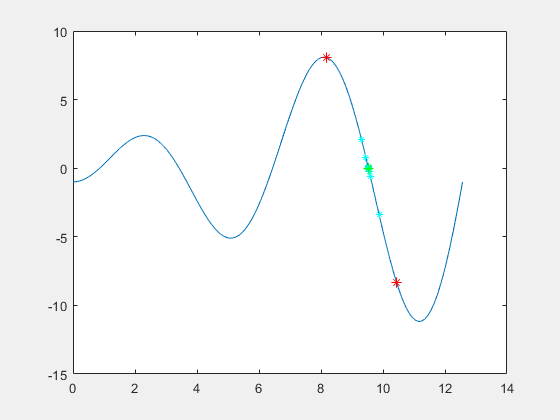

    "Верный корень:"    "9.5293"



    "Найденный корень:"    "9.5293"



Абсолютная погрешность: 0


p1 = ginput(1);
plot(p1(1), f(p1(1)), 'r*', 'MarkerSize', 7);
p2 = ginput(1);
plot(p2(1), f(p2(1)), 'r*', 'MarkerSize', 7);
if p1(1)>p2(1)
    p3 = p1;
    p1 = p2;
    p2 = p3;
end
x1 = p1(1);
x2 = p2(1);
if sign(f(p1(1))) ~= sign(f(p2(1)))
    while 1
        x0 = (x1+x2)/2;
        if x2-x1 < delta
            break;
        end
        if abs(x0) < eps
            break;
        end
        if sign(f(x0)) == sign(f(x2))
            x2 = x0;
        else
            x1 = x0;
        end
        plot(x0, f(x0), 'c*', 'MarkerSize', 5);
    end
    plot(x0, f(x0), 'g*', 'MarkerSize', 7);
    [xr, yr] = fzero(f, x0);
    format long;
    disp(["Верный корень:", xr]);
    disp(["Найденный корень:", x0]);
    a = abs(xr-x0);
    disp(['Абсолютная погрешность: ', num2str(a)]);
    
else
    error("У точек должны быть разные знаки");
end